# Testing and Verification

The purpose of testing is moreover a proof of concept that our model has satisfied the set of STL requirements. We have a document in this folder containing all the hard and soft requirements.

In order to verify correctness we will simulate the car through the parking lot using the costmap generated. We will use simulink toolbox for robotics and check if the requirements get satisfied. As the only tool which truly uses STLs for hybrid systems is breach. This file will be an attempt on incorporating both concepts.

InitBreach
clc;
clear S;
close all;

## Getting the Reference Path

addpath(pwd + "/../RRT");

ws = load(pwd + "/../RRT/input_variables_from_matlab_parking_example.mat");
startPose = ws.currentPose;
iterations = 2000;
dis = 10;
tolerance = 3;
minTurning = 4;
routePlan = ws.routePlan;
goalPoses = num2cell(routePlan.EndPose, 2);
for i = 1: length(goalPoses)
    goalPoses{i}(3) = deg2rad(goalPoses{i}(3));
end
costmap = ws.combinedMap;
tree = rrt(costmap, iterations, startPose, goalPoses{1}, minTurning, dis, tolerance);
[path, segments, Tree]= run(tree);

## Converting Dubins Segments to Ref_Path

sz = size(segments, 2);
ref_path = [];
for i = 1:sz
    segment_i = segments(i);
    segment_i = segment_i{1};
    segment_i = segment_i.PathPoses;
    sz_pose = size(segment_i, 1);
    for pose_idx = 1:sz_pose
        ref_path = cat(1, ref_path, segment_i(pose_idx,:));
    end
end
xyt = ref_path';
xyt = xyt(:);
xyt = xyt(4:end, 1);

Ts = 1.0;
n_params = size(ref_path, 1);
params = cell((n_params-1)*3, 1);
countr = 1;
for jj=2:n_params
    params{countr    , 1} = sprintf('RefX_u%d',jj-2);
    params{countr + 1, 1} = sprintf('RefY_u%d',jj-2);
    params{countr + 2, 1} = sprintf('RefT_u%d',jj-2);
    countr = countr + 3;
end
startX = ref_path(1, 1);
startY = ref_path(1, 2);
startT = ref_path(1, 3);
S = BreachSimulinkSystem('TestRRT');

Found var startT in base workspace used by TestRRT_breach/Constant3.
Found var startX in base workspace used by TestRRT_breach/Constant1.
Found var startY in base workspace used by TestRRT_breach/Constant2.


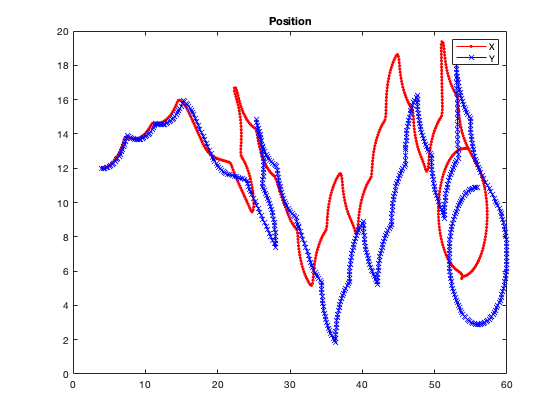

endTime = n_params;
tspan = 0:Ts:endTime;
% total_steps = endTime*Ts;
S.SetTime(tspan);
inputGen.type = 'UniStep';
inputGen.cp = n_params;
S.SetInputGen(inputGen);
S.SetParam(params, xyt);
numSimulations = 1;
S.QuasiRandomSample(numSimulations);
S.Sim;
signalValues = S.GetSignalValues({'x_out', 'y_out', 'Steering', 't_out'});
close all;
figure;
plot(signalValues(1,:)',signalValues(2,:)','-r.');
hold on;
plot(ref_path(:,1), ref_path(:,2), '-bx');
hold off;
title('Position');
legend('X','Y');

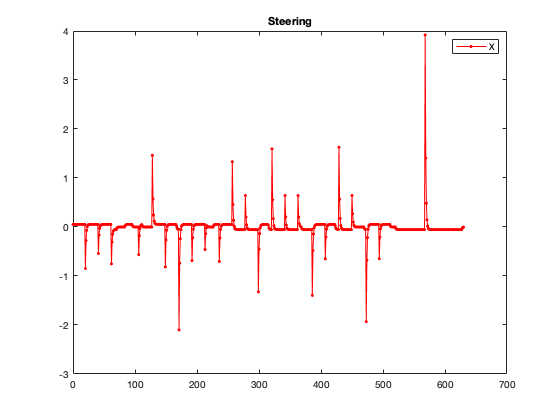

figure;
plot(tspan,signalValues(3,:)','-r.');
% title, legend code courtesy Ryan Blackwell
title('Steering');
legend('X','Y');